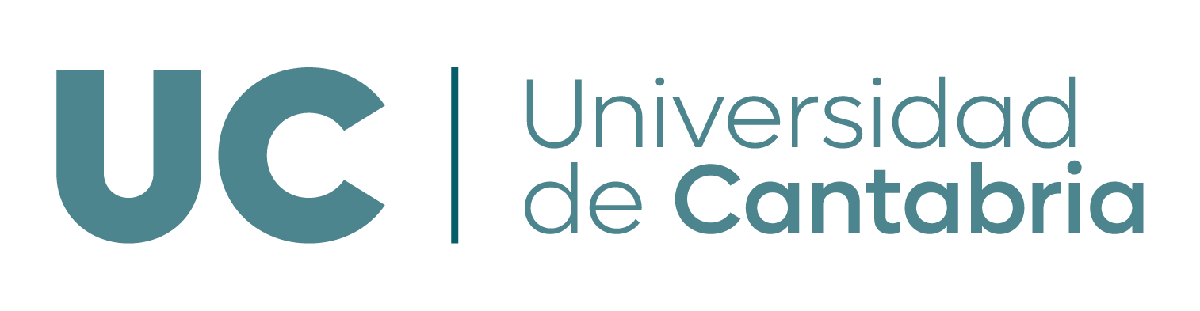

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# **Guion MATLAB: Proyección ortogonal y mínimos cuadrados**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Calcular y utilizar la matriz de proyección sobre un cierto subespacio

- Resolución (aproximada) de sistemas incompatibles por mínimos cuadrados

- Ajuste a una nube de puntos

**Funciones de MATLAB utilizadas en este guion: **` null, orth`

## **1. Proyección de un vector sobre un subespacio**

Para calcular la proyección de un vector sobre un subespacio hemos visto dos estrategias distintas:

- método 1: Dada una base ortogonal de $S$ podemos calcular como: $\text{proy}_\mathbf{S} (\vec{v}) = \text{proy}_{\vec{u}_1} (\vec{v}) + \text{proy}_{\vec{u}_2} (\vec{v}) + \dots + \text{proy}_{\vec{u}_p} (\vec{v})
$. Sino disponemos una base ortogonal de S podemos utilizar cualquiera de los procedimientos para ortogonalizar bases vistos anteriormente.

- método 2: Podemos calcular el vector proyección como a partir de la **matriz de proyección** que construiremos como: $proy_{S}(\vec{v})=P_S\vec{v}$

El uso de la matriz de proyección es más sencillo de implementar con MATLAB, mientras que sin ordenador el método 1 suele ser más adecuado.

### **1.1 Proyección ortogonal a partir de base ortogonal**

Dada la siguiente base (no ortogonal) de $S \subset \mathbb{R}^3$ y el vector $\[
\vec{v}=
\left(\begin{array}{c}
3\\
4\\
5
\end{array}\right)
\]
$.

v = [3 4 5]';  % vector a proyectar
baseS = [2 -1 1; -1 2 1]';  % base de S (es un sist. gen. y los vectores son l.i.). 

 Vamos a hallar la proyección ortogonal del vector $\vec{v}$sobre el subespacio $S$ $\text{proy}_\mathbf{S} (\vec{v}) = \text{proy}_{\vec{u}_1} (\vec{v}) + \text{proy}_{\vec{u}_2} (\vec{v}) + \dots + \text{proy}_{\vec{u}_p} (\vec{v})
$

Para ello lo primero necesitamos una base ortogonal de $S$. Podemos utilizar cualquiera de los métodos de ortogonalización vistos en el punto 3 del anterior guion, como el método de Gram-Schmidt o la función orth de MATLAB.

%guardamos en v1 y v2 los vectores de la base (no ortogonal)
v1=baseS(:,1);v2=baseS(:,2);
%Gram-Schmidt (conjunto de 2 vectores)
u1=v1;
u2=v2-dot(v2,u1)/dot(u1,u1)*u1

u2 =          0
    1.5000
    1.5000


dot(u1,u2)%comprobación base ortogonal

ans = 0

Obtenemos el vector correspondiente a la proyección ortogonal de v sobre S como suma de las proyecciónes ortogonales de v sobre cada uno de los vectores de la base ortogonal de  $S$ $B_{S}=\{ \vec{u}_1,\vec{u}_2 \}$


$$\text{proy}_\mathbf{S} (\vec{v}) = \text{proy}_{\vec{u}_1} (\vec{v}) + \text{proy}_{\vec{u}_2} (\vec{v}) 
$$


proy_v_u1=dot(v,u1)/dot(u1,u1)*u1;%proyección de v sobre el vector u1
proy_v_u2=dot(v,u2)/dot(u2,u2)*u2;%proyección de v sobre el vector u2
%proyección de v sobre S 
proy_v_S=proy_u1_v+proy_u2_v

proy_S_v =     2.3333
    3.3333
    5.6667


### **1.2 Matriz de proyección**

La matriz de proyección sobre un subespacio $S$ se obtiene como $P_S=B_S(B_{S}^{t}B_S)^_{-1}B_{S}^t$, donde $B_S$ es una matriz que contiene en sus columnas los vectores de una base (cualquiera, no tiene por qué ser ortogonal/ortonormal) de $S$. Por tanto, para hallar la matriz de proyección sobre un subespacio $S = <(2,-1,1), (-1,2,1)>$ de $\mathbb{R}^3$:

baseS = [2 -1 1; -1 2 1]';  % base de S (es un sist. gen. y los vectores son l.i.). 
dot(baseS(:,1), baseS(:,2))  % vemos que esta base NO es ortogonal

ans = -3

PS = baseS*inv(baseS'*baseS)*baseS'  % matriz de proyección sobre S

PS =     0.6667   -0.3333    0.3333
   -0.3333    0.6667    0.3333
    0.3333    0.3333    0.6667


La matriz de proyección $P_S$ siempre tiene dimensiones las del espacio vectorial al que pertenece el subespacio sobre el que proyectamos, aquí  $\mathbb{R}^3$. Además es una matriz simétrica. 

Una vez obtenida $P_S$ podemos obtener la proyección del vector $\vec{v}$ sobre $S$ como $proy_{S}(\vec{v})=P_S\vec{v}$. Por ejemplo, para proyectar ortogonalmente el vector $(3,4,5)$ sobre $S$:

v = [3 4 5]';  % vector a proyectar
proy_v_S=PS*v  % proyección de v sobre S

proy_S_v =     2.3333
    3.3333
    5.6667


Además, otra caracteristica interesante de la matriz de proyección $P_S$ es que los vectores de sus columnas forman un sistema generador de $S$. ¿Qué rango deberá tener por tanto $P_S$ ?

rank(PS)

ans = 2

## **2. Resolución (aproximada) de sistemas incompatibles por mínimos cuadrados**

### **2.1 Ejemplo: Columnas de A linealmente dependientes**

Imaginemos el siguiente sistema de ecuaciones lineales:


$$\textstyle\left\{  \begin{array}{rcr}
			 x  -y & = & 1\\ 
			 y + z & = & 0\\
			 x +y+2z & = & -1\\  
		 \end{array}\right.$$


Es fácil comprobar por el Teorema de Rouché Forbenius que es incompatible (no tiene solución):

A = [1 -1 0; 0 1 1; 1 1 2];  % matriz de coeficientes
b = [1 0 -1]';  % vector de términos independientes
Aamp = [A b];  % matriz ampliada
[rank(A) rank(Aamp)]  % S.I.

ans =      2     3


Hemos visto que en estas circunstancias siempre es posible obtener una solución aproximada por mínimos cuadrados. Se trataría de sustituir el vector de términos indpendientes $\vec{b}$, para el cual no existe solución, por otro vector $\hat{\vec{b}}$ para el cual el sistema sí tenga solución. Este vector $\hat{\vec{b}}$ será la proyección de $\vec{b}$ sobre el subespacio generado por las columnas de $A$ (subespacio columna $colA$). Para calcular la proyección de $\vec{b}$sobre el espacio columna ($colA$) necesitaremos una base de $colA$. Puesto que ya tenemos un sistema generador, simplemente tenemos que comprobar si las columnas de A son l.i.: 

rref(A)  % rg(A)=2, las columnas son son l.d.

ans =      1     0     1
     0     1     1
     0     0     0


El espacio vectorial columna de A tiene dimensión 2. Podemos obtener una base del espacio vectorial columna de$A$ simplemente quedándonos con las columnas pivotales.

basecolA=A(:,[1,2])

basecolA =      1    -1
     0     1
     1     1


Ahora ya estamos en condiciones de calcular la matriz de proyección sobre el subespacio generado por las columnas de $A$, puesto que conocemos una base del mismo. A partir de esta base obtendremos la matriz de proyección que nos permitirá encontrar el vector $\hat{\vec{b}}$ para el cual el sistema pasa a ser compatible.

P = basecolA*inv(basecolA'*basecolA)*basecolA'  % matriz de proyección 

P =     0.8333   -0.3333    0.1667
   -0.3333    0.3333    0.3333
    0.1667    0.3333    0.8333


bhat = P*b  % vector para el cual el sistema pasa a ser compatible. Es

bhat =     0.6667
   -0.6667
   -0.6667


Si comparamos el nuevo vector de términos independientes $\hat{\vec{b}}$ con el del sistema original vemos que no se parecen demasiado. Sin embargo el vector $\hat{\vec{b}}$ es el vector perteneciente al espacio columna lo más parecido posible a $\vec{b}$, es decir,   $\hat{\vec{b}}$ es el vector lo más próximo posible a $\vec{b}$ que nos permite obtener un sistema $A \vec{x}=\hat{\vec{b}}$ que sea compatible.  

Comprobemos que $A \vec{x}=\hat{\vec{b}}$ es ahora un sistema compatible.

[rank(A), rank([A b])]  % S.C.I.

ans =      2     3


Nuestro nuevo sistema (el que resulta de sustituir $\vec{b}$ por $\hat{\vec{b}}$) es compatible indeterminado (infinitas soluciones). Tenemos 3 incógnitas y el rango de la matriz de coeficientes es 2, luego habrá un parámetro libre. Ya sabemos cómo resolver este tipo de sistemas:

syms x y z real

syms requires Symbolic Math Toolbox.

X = [x y z]';  % vector de incógnitas simbólicas
sol = solve(A*X == bhat, [x y])  % resuelvo en las incógnitas principales (columnas pivotales de A)
xhat = [sol.x sol.y z]'% solución aproximada por mínimos cuadrados

Siempre es recomendable comprobar que la solución que hemos hallado es correcta:

% Compruebo que así sea para un valor cualquiera del parámetro z
A*subs(xhat, z, 2.365) - c   % para z=2.365

Y en cualquier caso el error cuadrático cometido sería:

norm(b-bhat)^2  % error cuadrático 

$\hat{\vec{x}}$ es la mejor aproximación que podemos encontrar para el sistema $A\vec{x}=\vec{b}$, aunque obviamente no es solución del sistema incompatible, como podemos comprobar

A*xhat-b% difiere del vector nulo, xhat es solo una aproximación, no es solución

### **2.2 Ejemplo: Columnas de A linealmente independientes**

Si las columnas de la matriz de coeficientes del sistema incompatible que trato de resolver son l.i., el proceso se simplifica, puesto que una vez que hallemos nuestro $\hat{\vec{b}}$, nos quedará un S.C.D. con una única solución, que podríamos resolver directamente por medio del operador "\". Consideremos, en el siguiente sistema:


$$\textstyle\left\{  \begin{array}{rcr}
			 -x  + 4y & = & 15\\ 
			 y & = & 6\\
			 -y & = & 4\\  
			 x -2y & = & -5\\  
		 \end{array}\right.$$


A = [-1 4; 0 1; 0 -1; 1 -2];  % matriz de coeficientes
b = [15 6 4 -5]';  % vector de términos independientes
[rank(A) rank([A b])]  % S.I.

El rango de la matriz de coeficientes es 2, y está tiene 2 columnas. Luego las columnas de A forman una base del espacio columna.

basecolA=A;
P = basecolA*inv(basecolA'*basecolA)*basecolA'  % matriz de proyección 
bhat=P*b

Comprobemos que en efecto es un S.C.D

[rank(A), rank([A bhat])]  % S.C.D.

Al ser un S.C.D podemos hallar fácilmente su única solución mediante el operador "\"

xhat=A\bhat

Acabamos de hallar que la solución de mínimos cuadrados es $x=-1, y=3$. Esto quiere decir que el vector $\hat{\vec{b}}$ se puede expresar como combinación lineal de las columnas de $A$, siendo los coeficientes de dicha C.L. $-1$ y $3$.

$\hat{\vec{x}}$ es la mejor aproximación que podemos encontrar para el sistema $A\vec{x}=\vec{b}$, aunque obviamente no es solución del sistema incompatible, como podemos comprobar

A*xhat-b% difiere del vector nulo, xhat es solo una aproximación, no es solución

### 2.3 Uso de A\b para encontrar solución de mínimos cuadrados

**Recordatorio**: El operador A\b nos permitía resolver rápidamente S.C.D. Sin embargo, recordemos que debíamos tener cuidado en su uso en S.C.I. (ya nos devuelve una única solución de las infinitas posibles) y en S.I., ya que nos devuelve un vector que no es solución. ¡Este vector es justo una solución particular de mínimos cuadrados!

Si intentamos resolver directamente un sistema incompatible mediante el operador "\" MATLAB nos devolverá una solución por mínimos cuadrados, pero es importante distinguir entre estos dos casos:

- Si las columnas de son l.i. entonces $A \vec{x}=\hat{\vec{b}}$será S.C.D y `A\b` nos devolverá directamente la solución por mínimos cuadrados

%otra manera directa de encontrar la solución por mínimos cuadrados para el ejemplo 2
A\b

- Si las columnas de son l.d. entonces $A \vec{x}=\hat{\vec{b}}$será S.C.I y `A\b` nos devolverá una solución particular de las infintas soluciones posibles de mínimos cuadrados. Comprueba tu mismo que para el ejemplo 1 `A\b `obtiene una de las infinitas soluciones obtenidas por mínimos cuadrados.

### **2.4. Aplicación: Ajuste a una nube de puntos**

Hemos visto que dada una nube de puntos, se puede ajustar por un tipo de función predefinida (por ejemplo una recta, una parábola, una exponencial, etc.). Para ello habría que resolver el sistema que resulte de forzar a que nuestra función aproximadora pase por todos los puntos de la nube. Previsiblemente, este sistema será incompatible (no tendrá solución). Sin embargo, podremos buscar una solución aproximada por mínimos cuadrados. A modo de ejemplo, imaginemos que tenemos los siguientes datos experimentales relativos a la medida de la intensidad de corriente que atraviesa un hilo conductor para distintos voltajes:

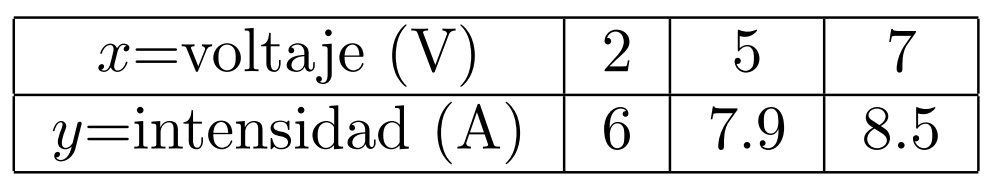

Para obtener un ajuste lineal (es decir, una recta $y=mx+n$), habría que resolver el sistema


$$\textstyle\left\{  \begin{array}{rcr}
			 2m  + n & = & 6\\ 
			 5m + n & = & 7.9\\
			 7m +n & = & 8.5\\  
		 \end{array}\right.$$


en el que las incógnitas serán $m$ y $n$ (coeficientes de la recta de ajuste). Lo resolvemos:

x0 = [2 5 7];  % coordenada x de los puntos de la nube
y0 = [6 7.9 8.5];  % coordenada y de los puntos de la nube
A = [x0', ones(length(x0), 1)]  % matriz de coeficientes del sistema a resolver
b = y0'  % vector de términos independientes del sistema a resolver
[rank(A) rank([A b])]  % S.I.

Las columnas de $A$ son L.I. ($rg(A)=2$), por lo que podemos calcular directamente la solución de mínimos cuadrados como:

xhat = inv(A'*A)*A'*b  % solución de mínimos cuadrados

El primerelemento de esta solución será el coeficiente $m$ de nuestro ajuste lineal, y el segundo la $n$. Por tanto, el polinomio aproximador buscado es $y=0.5105x+5.0842$.

## Ejercicios propuestos

**Ejercicio 1:**

En $\mathbb{R}^4$, obtén una base del complemento ortogonal del subespacio $S=\lbrace (\alpha, 0, 2\alpha, \alpha): \alpha \in \mathbb{R}\rbrace$. Verifica que $S^\perp$ es ortogonal a $S$ y que $S$ y $S^\perp$ son subespacios complementarios/suplementarios.

**Ejercicio 2:**

En $\mathbb{R}^3$, proyecta ortogonalmente el vector $\vec{v} = (3,2,2)$ sobre el subespacio $S=<(2,0,1),(0,3,-1),(2,3,0)>$ utilizando la matriz de proyección. Calcula dicha matriz partiendo de dos bases de $S$ distintas, una de ellas ortonormal y la otra no. ¿Qué sucede?

**Ejercicio 3:**

Utilizando matrices de proyección, calcula la proyección ortogonal del vector $$\vec{v} = (3, 4, 5)$$ sobre el subpespacio $S : \lbrace x-y+z=0 \rbrace$ de $\mathbb{R}^3$ y sobre $S^\perp$. Comprueba que ambas proyecciones son ortogonales entre sí y que $\vec{v}$ puede expresarse como la suma de ambas. ¿Qué pasa si sumas la matriz de proyección sobre $S$ y la matriz de proyección sobre $S^\perp$?

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.